Init

clear
clc
hold off

Constant

c = get_constants;

Shear and Moment

function [reaction_a,reaction_b] = reaction_forces(train_distance,train_load)
    % given the start of the train is x m from the left,
    % return the reaction forces at each support.
    
    % this only concerns vertical forces, since no
    % horizontal load is applied.
    
    % constraints: 0 <= x <= length - length of train
    c = get_constants();
    
    train_moments_a = train_distance .* train_load;
    reaction_b = sum(train_moments_a) / c.LENGTH;
    reaction_a = sum(train_load) - reaction_b;
end

function [V,M] = shear_and_moment(x,train_position)
    c = get_constants();

    train_distance = c.TRAIN_DIM;
    load_factor = c.LOAD_FACTOR;
    if (load_factor == -1)
        train_load = c.TRAIN_LOAD_1;
    else
        train_load = load_factor * c.TRAIN_LOAD_2;
    end

    cumulative_distances = cumsum(train_distance(1:end-1)) + train_position;
    [reaction_a, reaction_b] = reaction_forces(cumulative_distances,train_load);

    % SFD
    SFD_forces = [reaction_a -train_load reaction_b];
    SFD_net_forces = cumsum(SFD_forces);
    force_distances = [0 cumulative_distances c.LENGTH];

    SFD = [force_distances; SFD_net_forces];

    % BMD

    distance_intervals = abs(force_distances(2:end) - force_distances(1:end-1));
    BMD_moments = SFD_net_forces(1:end-1) .* distance_intervals;
    BMD_net_moments = cumsum(BMD_moments);

    BMD = [force_distances;[0,BMD_net_moments]];

    %remove dupes (horrible fix also but whatever
    [force_distances_u, ~, idx] = unique(force_distances, 'stable');
    lastIdx = accumarray(idx(:), (1:numel(idx)).', [], @max);
    % evaluated (i know this whole function computationally SUCKS but its easier)
    V = interp1(force_distances_u, SFD(2,lastIdx), x, 'previous', 'extrap');
    M = interp1(force_distances_u, BMD(2,lastIdx), x, 'linear', 'extrap');
end


Moment of Inertia

function height = h(x, min_height, max_height)
    if 0 <= x && x < 60 || 1200 <= x
        height = min_height;
    elseif 60 <= x && x < 280
        height = min_height + (max_height-min_height)/(280 - 60) * (x - 60);
    elseif 280 <= x && x < 980
        height = max_height;
    elseif 980 <= x && x < 1200
        height = max_height - (max_height-min_height)/(280 - 60) * (x - 980);
    end
end

function thickness = t(x,lower_amnt,upper_amnt)
    c = get_constants();
    if 0 <= x && x < 280 || 980 <= x
        thickness = c.STANDARD_WIDTH * lower_amnt;
    else
        thickness = c.STANDARD_WIDTH * upper_amnt;
    end
end

function I = get_moment_of_inertia(x, instead_centroid)
    % proportional for now
    % define a matrix containing info such that
    arguments
        x double
        instead_centroid = 0
    end

    c = get_constants();

    parts = ["top flange"; "left web"; "right web"; "bottom flange"];
    height = h(x,c.MIN_HEIGHT,c.MAX_HEIGHT);

    web_area = c.STANDARD_WIDTH*(height-t(x,2,3));
    areas = [100*t(x,1,2),web_area,web_area,100*c.STANDARD_WIDTH];
    centroids = [height-.5*t(x,1,2),c.STANDARD_WIDTH + 0.5*(height - t(x,2,3)),c.STANDARD_WIDTH + 0.5*(height - t(x,2,3)),.5*c.STANDARD_WIDTH];

    centroid = sum(areas.*centroids)/sum(areas);
    distances = abs(centroids-centroid);

    parallel_axes = areas .* (distances.^2);
    Is = (1/12) * [100 c.STANDARD_WIDTH c.STANDARD_WIDTH 100] .* ([t(x,1,2) height-t(x,2,3) height-t(x,2,3) c.STANDARD_WIDTH].^3);
    I = sum(Is) + sum(parallel_axes);

    if instead_centroid == 1 % might be the worst thing I've ever written but oh well
        I = centroid;
    end
end

Bending Stress

function [bottom_stress,top_stress] = bending_stress(x, train_position)
    c = get_constants();
    [~,M] = shear_and_moment(x, train_position);

    I = get_moment_of_inertia(x);
    ys = [get_moment_of_inertia(x,1) abs(h(x, c.MIN_HEIGHT, c.MAX_HEIGHT) - get_moment_of_inertia(x,1))];
    stresses = M * ys / I;
    bottom_stress = stresses(1);
    top_stress = stresses(2);
end

Shear Stress

function Q = get_Q(x, y) % please input this from the bottom
    c = get_constants();
    NA = get_moment_of_inertia(x,1); % neutral axis

    if y < c.STANDARD_WIDTH
        % we are in the bottom
        Q = (100 * y) * abs(NA - y / 2);
    elseif h(x, c.MIN_HEIGHT, c.MAX_HEIGHT) - y < t(x,1,2)
        % we are in the top
        Q = (100 * (h(x, c.MIN_HEIGHT, c.MAX_HEIGHT) - y)) * abs(NA - (h(x, c.MIN_HEIGHT, c.MAX_HEIGHT) - y) / 2);
    else
        Q = (100 * c.STANDARD_WIDTH * abs(NA - .5 * c.STANDARD_WIDTH) + 2 * (c.STANDARD_WIDTH*(y-c.STANDARD_WIDTH) * abs(NA - (c.STANDARD_WIDTH + .5 * (y - c.STANDARD_WIDTH)))));
    end
end

function central_stress = shear_stress(x, y, train_position)
    c = get_constants();
    V = shear_and_moment(x,train_position); % just first element (shear)
    Q = get_Q(x, y);
    I = get_moment_of_inertia(x);
    if y < c.STANDARD_WIDTH || y > h(x,c.MIN_HEIGHT,c.MAX_HEIGHT) - c.STANDARD_WIDTH
        B = 100;
    else
        B = 2 * c.STANDARD_WIDTH;
    end
    central_stress = (V*Q) / (I*B);
end

Tests

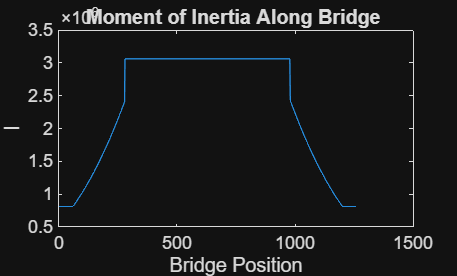

steps = 0:2:1260;
plot(steps,arrayfun(@get_moment_of_inertia,steps))
title('Moment of Inertia Along Bridge ')
xlabel("Bridge Position")
ylabel("I")
hold off


get_Q(630, get_moment_of_inertia(630,1)) % at middle of bridge and cross section

ans = 2.2211e+04

get_Q(0, get_moment_of_inertia(0,1)) % at edge of bridge and middle of cross section

ans = 9.2851e+03

get_Q(0, 0) % at edge of bridge and cross section

ans = 0

shear_stress(0, get_moment_of_inertia(0,1),0) 

ans = 2.6636

Optimization

max_bottom_bending_stress = [0 0 0]; % [i,bridge_position,value]
max_top_bending_stress = [0 0 0]; % [i,value]
max_central_shear_stress = [0 0 0];
train_positions = 0:1:300;
for i = train_positions
    [bottom_bending_stress, top_bending_stress] = arrayfun(@(x) bending_stress(x, i),steps);
    central_shear_stress = arrayfun(@(x) shear_stress(x,get_moment_of_inertia(x,1),i),steps);

    [bottomMax, bottomIdx] = max(bottom_bending_stress);
    [topMax, topIdx] = max(top_bending_stress);
    [shearMax, shearIdx] = max(central_shear_stress)

    if bottomMax > max_bottom_bending_stress(3)
        max_bottom_bending_stress = [i, steps(bottomIdx), bottomMax];
    end

    if topMax > max_top_bending_stress(3)
        max_top_bending_stress = [i, steps(topIdx), topMax];
    end

    if shearMax > max_central_shear_stress(3)
        max_central_shear_stress = [i, steps(shearIdx), shearMax];
    end
end

shearMax = 2.6636

shearIdx = 1

shearMax = 2.6600

shearIdx = 1

shearMax = 2.6564

shearIdx = 1

shearMax = 2.6529

shearIdx = 1

shearMax = 2.6493

shearIdx = 1

shearMax = 2.6457

shearIdx = 1

shearMax = 2.6421

shearIdx = 1

shearMax = 2.6386

shearIdx = 1

shearMax = 2.6350

shearIdx = 1

shearMax = 2.6314

shearIdx = 1

shearMax = 2.6278

shearIdx = 1

shearMax = 2.6242

shearIdx = 1

shearMax = 2.6207

shearIdx = 1

shearMax = 2.6171

shearIdx = 1

shearMax = 2.6135

shearIdx = 1

shearMax = 2.6099

shearIdx = 1

shearMax = 2.6064

shearIdx = 1

shearMax = 2.6028

shearIdx = 1

shearMax = 2.5992

shearIdx = 1

shearMax = 2.5956

shearIdx = 1

shearMax = 2.5920

shearIdx = 1

shearMax = 2.5885

shearIdx = 1

shearMax = 2.5849

shearIdx = 1

shearMax = 2.5813

shearIdx = 1

shearMax = 2.5777

shearIdx = 1

shearMax = 2.5742

shearIdx = 1

shearMax = 2.5706

shearIdx = 1

shearMax = 2.5670

shearIdx = 1

shearMax = 2.5634

shearIdx = 1

shearMax = 2.5598

shearIdx = 1

shearMax = 2.5563

shearIdx = 1

shearMax = 2.5527

shearIdx = 1

shearMax = 2.5491

shearIdx = 1

shearMax = 2.5455

shearIdx = 1

shearMax = 2.5420

shearIdx = 1

shearMax = 2.5384

shearIdx = 1

shearMax = 2.5348

shearIdx = 1

shearMax = 2.5312

shearIdx = 1

shearMax = 2.5276

shearIdx = 1

shearMax = 2.5241

shearIdx = 1

shearMax = 2.5205

shearIdx = 1

shearMax = 2.5169

shearIdx = 1

shearMax = 2.5133

shearIdx = 1

shearMax = 2.5098

shearIdx = 1

shearMax = 2.5062

shearIdx = 1

shearMax = 2.5026

shearIdx = 1

shearMax = 2.4990

shearIdx = 1

shearMax = 2.4954

shearIdx = 1

shearMax = 2.4919

shearIdx = 1

shearMax = 2.4883

shearIdx = 1

shearMax = 2.4847

shearIdx = 1

shearMax = 2.4811

shearIdx = 1

shearMax = 2.4776

shearIdx = 1

shearMax = 2.4740

shearIdx = 1

shearMax = 2.4704

shearIdx = 1

shearMax = 2.4668

shearIdx = 1

shearMax = 2.4632

shearIdx = 1

shearMax = 2.4597

shearIdx = 1

shearMax = 2.4561

shearIdx = 1

shearMax = 2.4525

shearIdx = 1

shearMax = 2.4489

shearIdx = 1

shearMax = 2.4454

shearIdx = 1

shearMax = 2.4418

shearIdx = 1

shearMax = 2.4382

shearIdx = 1

shearMax = 2.4346

shearIdx = 1

shearMax = 2.4310

shearIdx = 1

shearMax = 2.4275

shearIdx = 1

shearMax = 2.4239

shearIdx = 1

shearMax = 2.4203

shearIdx = 1

shearMax = 2.4167

shearIdx = 1

shearMax = 2.4132

shearIdx = 1

shearMax = 2.4096

shearIdx = 1

shearMax = 2.4060

shearIdx = 1

shearMax = 2.4024

shearIdx = 1

shearMax = 2.3988

shearIdx = 1

shearMax = 2.3953

shearIdx = 1

shearMax = 2.3917

shearIdx = 1

shearMax = 2.3881

shearIdx = 1

shearMax = 2.3845

shearIdx = 1

shearMax = 2.3810

shearIdx = 1

shearMax = 2.3774

shearIdx = 1

shearMax = 2.3738

shearIdx = 1

shearMax = 2.3702

shearIdx = 1

shearMax = 2.3666

shearIdx = 1

shearMax = 2.3631

shearIdx = 1

shearMax = 2.3595

shearIdx = 1

shearMax = 2.3559

shearIdx = 1

shearMax = 2.3523

shearIdx = 1

shearMax = 2.3488

shearIdx = 1

shearMax = 2.3452

shearIdx = 1

shearMax = 2.3416

shearIdx = 1

shearMax = 2.3380

shearIdx = 1

shearMax = 2.3344

shearIdx = 1

shearMax = 2.3309

shearIdx = 1

shearMax = 2.3273

shearIdx = 1

shearMax = 2.3237

shearIdx = 1

shearMax = 2.3201

shearIdx = 1

shearMax = 2.3166

shearIdx = 1

shearMax = 2.3130

shearIdx = 1

shearMax = 2.3094

shearIdx = 1

shearMax = 2.3058

shearIdx = 1

shearMax = 2.3022

shearIdx = 1

shearMax = 2.2987

shearIdx = 1

shearMax = 2.2951

shearIdx = 1

shearMax = 2.2915

shearIdx = 1

shearMax = 2.2879

shearIdx = 1

shearMax = 2.2844

shearIdx = 1

shearMax = 2.2808

shearIdx = 1

shearMax = 2.2772

shearIdx = 1

shearMax = 2.2736

shearIdx = 1

shearMax = 2.2700

shearIdx = 1

shearMax = 2.2665

shearIdx = 1

shearMax = 2.2629

shearIdx = 1

shearMax = 2.2593

shearIdx = 1

shearMax = 2.2557

shearIdx = 1

shearMax = 2.2522

shearIdx = 1

shearMax = 2.2486

shearIdx = 1

shearMax = 2.2450

shearIdx = 1

shearMax = 2.2414

shearIdx = 1

shearMax = 2.2378

shearIdx = 1

shearMax = 2.2343

shearIdx = 1

shearMax = 2.2307

shearIdx = 1

shearMax = 2.2271

shearIdx = 1

shearMax = 2.2235

shearIdx = 1

shearMax = 2.2200

shearIdx = 1

shearMax = 2.2164

shearIdx = 1

shearMax = 2.2128

shearIdx = 1

shearMax = 2.2092

shearIdx = 1

shearMax = 2.2056

shearIdx = 1

shearMax = 2.2021

shearIdx = 1

shearMax = 2.1985

shearIdx = 1

shearMax = 2.1949

shearIdx = 1

shearMax = 2.1913

shearIdx = 1

shearMax = 2.1878

shearIdx = 1

shearMax = 2.1842

shearIdx = 1

shearMax = 2.1806

shearIdx = 1

shearMax = 2.1770

shearIdx = 1

shearMax = 2.1734

shearIdx = 1

shearMax = 2.1699

shearIdx = 1

shearMax = 2.1663

shearIdx = 1

shearMax = 2.1627

shearIdx = 1

shearMax = 2.1591

shearIdx = 1

shearMax = 2.1556

shearIdx = 1

shearMax = 2.1520

shearIdx = 1

shearMax = 2.1484

shearIdx = 1

shearMax = 2.1448

shearIdx = 1

shearMax = 2.1412

shearIdx = 1

shearMax = 2.1377

shearIdx = 1

shearMax = 2.1341

shearIdx = 1

shearMax = 2.1305

shearIdx = 1

shearMax = 2.1269

shearIdx = 1

shearMax = 2.1234

shearIdx = 1

shearMax = 2.1198

shearIdx = 1

shearMax = 2.1162

shearIdx = 1

shearMax = 2.1126

shearIdx = 1

shearMax = 2.1090

shearIdx = 1

shearMax = 2.1055

shearIdx = 1

shearMax = 2.1019

shearIdx = 1

shearMax = 2.0983

shearIdx = 1

shearMax = 2.0947

shearIdx = 1

shearMax = 2.0911

shearIdx = 1

shearMax = 2.0876

shearIdx = 1

shearMax = 2.0840

shearIdx = 1

shearMax = 2.0804

shearIdx = 1

shearMax = 2.0768

shearIdx = 1

shearMax = 2.0733

shearIdx = 1

shearMax = 2.0697

shearIdx = 1

shearMax = 2.0661

shearIdx = 1

shearMax = 2.0625

shearIdx = 1

shearMax = 2.0589

shearIdx = 1

shearMax = 2.0554

shearIdx = 1

shearMax = 2.0518

shearIdx = 1

shearMax = 2.0482

shearIdx = 1

shearMax = 2.0446

shearIdx = 1

shearMax = 2.0411

shearIdx = 1

shearMax = 2.0375

shearIdx = 1

shearMax = 2.0339

shearIdx = 1

shearMax = 2.0303

shearIdx = 1

shearMax = 2.0267

shearIdx = 1

shearMax = 2.0232

shearIdx = 1

shearMax = 2.0196

shearIdx = 1

shearMax = 2.0160

shearIdx = 1

shearMax = 2.0124

shearIdx = 1

shearMax = 2.0089

shearIdx = 1

shearMax = 2.0053

shearIdx = 1

shearMax = 2.0017

shearIdx = 1

shearMax = 1.9981

shearIdx = 1

shearMax = 1.9945

shearIdx = 1

shearMax = 1.9910

shearIdx = 1

shearMax = 1.9874

shearIdx = 1

shearMax = 1.9838

shearIdx = 1

shearMax = 1.9802

shearIdx = 1

shearMax = 1.9767

shearIdx = 1

shearMax = 1.9731

shearIdx = 1

shearMax = 1.9695

shearIdx = 1

shearMax = 1.9659

shearIdx = 1

shearMax = 1.9623

shearIdx = 1

shearMax = 1.9588

shearIdx = 1

shearMax = 1.9552

shearIdx = 1

shearMax = 1.9516

shearIdx = 1

shearMax = 1.9480

shearIdx = 1

shearMax = 1.9445

shearIdx = 1

shearMax = 1.9409

shearIdx = 1

shearMax = 1.9373

shearIdx = 1

shearMax = 1.9337

shearIdx = 1

shearMax = 1.9301

shearIdx = 1

shearMax = 1.9266

shearIdx = 1

shearMax = 1.9230

shearIdx = 1

shearMax = 1.9194

shearIdx = 1

shearMax = 1.9158

shearIdx = 1

shearMax = 1.9123

shearIdx = 1

shearMax = 1.9087

shearIdx = 1

shearMax = 1.9051

shearIdx = 1

shearMax = 1.9015

shearIdx = 1

shearMax = 1.8979

shearIdx = 1

shearMax = 1.8944

shearIdx = 1

shearMax = 1.8908

shearIdx = 1

shearMax = 1.8872

shearIdx = 1

shearMax = 1.8836

shearIdx = 1

shearMax = 1.8801

shearIdx = 1

shearMax = 1.8765

shearIdx = 1

shearMax = 1.8729

shearIdx = 1

shearMax = 1.8693

shearIdx = 1

shearMax = 1.8657

shearIdx = 1

shearMax = 1.8622

shearIdx = 1

shearMax = 1.8586

shearIdx = 1

shearMax = 1.8550

shearIdx = 1

shearMax = 1.8514

shearIdx = 1

shearMax = 1.8479

shearIdx = 1

shearMax = 1.8443

shearIdx = 1

shearMax = 1.8407

shearIdx = 1

shearMax = 1.8371

shearIdx = 1

shearMax = 1.8335

shearIdx = 1

shearMax = 1.8300

shearIdx = 1

shearMax = 1.8264

shearIdx = 1

shearMax = 1.8228

shearIdx = 1

shearMax = 1.8192

shearIdx = 1

shearMax = 1.8157

shearIdx = 1

shearMax = 1.8121

shearIdx = 1

shearMax = 1.8085

shearIdx = 1

shearMax = 1.8049

shearIdx = 1

shearMax = 1.8013

shearIdx = 1

shearMax = 1.7978

shearIdx = 1

shearMax = 1.7942

shearIdx = 1

shearMax = 1.7906

shearIdx = 1

shearMax = 1.7870

shearIdx = 1

shearMax = 1.7835

shearIdx = 1

shearMax = 1.7799

shearIdx = 1

shearMax = 1.7763

shearIdx = 1

shearMax = 1.7727

shearIdx = 1

shearMax = 1.7691

shearIdx = 1

shearMax = 1.7656

shearIdx = 1

shearMax = 1.7620

shearIdx = 1

shearMax = 1.7584

shearIdx = 1

shearMax = 1.7548

shearIdx = 1

shearMax = 1.7513

shearIdx = 1

shearMax = 1.7477

shearIdx = 1

shearMax = 1.7441

shearIdx = 1

shearMax = 1.7405

shearIdx = 1

shearMax = 1.7369

shearIdx = 1

shearMax = 1.7334

shearIdx = 1

shearMax = 1.7298

shearIdx = 1

shearMax = 1.7262

shearIdx = 1

shearMax = 1.7226

shearIdx = 1

shearMax = 1.7191

shearIdx = 1

shearMax = 1.7155

shearIdx = 1

shearMax = 1.7119

shearIdx = 1

shearMax = 1.7083

shearIdx = 1

shearMax = 1.7047

shearIdx = 1

shearMax = 1.7012

shearIdx = 1

shearMax = 1.6976

shearIdx = 1

shearMax = 1.6940

shearIdx = 1

shearMax = 1.6904

shearIdx = 1

shearMax = 1.6869

shearIdx = 1

shearMax = 1.6833

shearIdx = 1

shearMax = 1.6797

shearIdx = 1

shearMax = 1.6761

shearIdx = 1

shearMax = 1.6725

shearIdx = 1

shearMax = 1.6690

shearIdx = 1

shearMax = 1.6654

shearIdx = 1

shearMax = 1.6618

shearIdx = 1

shearMax = 1.6582

shearIdx = 1

shearMax = 1.6547

shearIdx = 1

shearMax = 1.6511

shearIdx = 1

shearMax = 1.6475

shearIdx = 1

shearMax = 1.6439

shearIdx = 1

shearMax = 1.6403

shearIdx = 1

shearMax = 1.6368

shearIdx = 1

shearMax = 1.6332

shearIdx = 1

shearMax = 1.6296

shearIdx = 1

shearMax = 1.6260

shearIdx = 1

shearMax = 1.6225

shearIdx = 1

shearMax = 1.6189

shearIdx = 1

shearMax = 1.6153

shearIdx = 1

shearMax = 1.6117

shearIdx = 1

shearMax = 1.6081

shearIdx = 1

shearMax = 1.6046

shearIdx = 1

shearMax = 1.6010

shearIdx = 1

shearMax = 1.5974

shearIdx = 1

shearMax = 1.5938

shearIdx = 1

shearMax = 1.5903

shearIdx = 1

disp('bottom');

bottom


fprintf('train pos: %g, bridge pos: %g, stress: %g\n', max_bottom_bending_stress(1), max_bottom_bending_stress(2), max_bottom_bending_stress(3));

train pos: 88, bridge pos: 656, stress: 5.69767


disp('top');

top


fprintf('train pos: %g, bridge pos: %g, stress: %g\n', max_top_bending_stress(1), max_top_bending_stress(2), max_top_bending_stress(3));

train pos: 248, bridge pos: 980, stress: 4.4473


disp('shear');

shear


fprintf('train pos: %g, bridge pos: %g, stress: %g\n', max_central_shear_stress(1), max_central_shear_stress(2), max_central_shear_stress(3));

train pos: 0, bridge pos: 0, stress: 2.6636


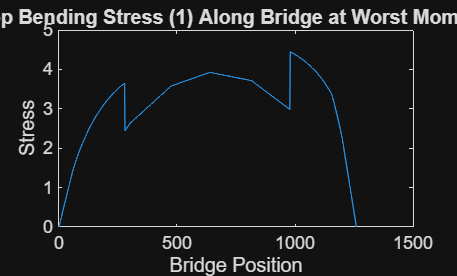



[~,top_bending_stress] = arrayfun(@(x) bending_stress(x, max_top_bending_stress(1)),steps);
plot(steps,top_bending_stress)
title('Top Bending Stress (1) Along Bridge at Worst Moment ')
xlabel("Bridge Position")
ylabel("Stress")

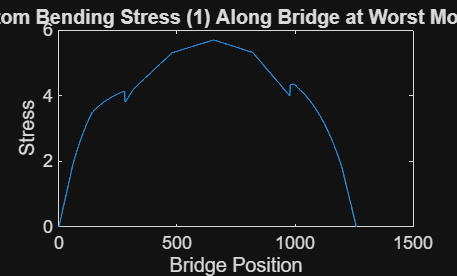


bottom_bending_stress = arrayfun(@(x) bending_stress(x, max_bottom_bending_stress(1)),steps);
plot(steps,bottom_bending_stress)
title('Bottom Bending Stress (1) Along Bridge at Worst Moment ')
xlabel("Bridge Position")
ylabel("Stress")

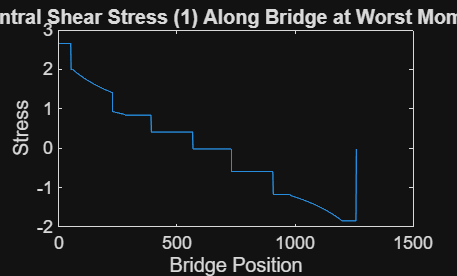


central_shear_stress = arrayfun(@(x) shear_stress(x, get_moment_of_inertia(x,1), max_central_shear_stress(1)),steps);
plot(steps,central_shear_stress)
title('Central Shear Stress (1) Along Bridge at Worst Moment ')
xlabel("Bridge Position")
ylabel("Stress")